# **Wine Quality**

# *1. Import & Organize*

## 1. Import data

Import the data in `wineQuality.csv` into a table.

data = readtable("wineQuality.csv")

data = 6497×13 table
    fixedacidity    volatileacidity    citricacid    residualsugar    chlorides    freesulfurdioxide    totalsulfurdioxide    density     pH     sulphates    alcohol    quality      Color  
    ____________    _______________    __________    _____________    _________    _________________    __________________    _______    ____    _________    _______    _______    _________

        7.1               0.26            0.49            2.2           0.032             31                   113             0.9903    3.37      0.42        12.9        92       {'White'}
        9.1               0.27            0.45           10.6           0.035             28                   124              0.997     3.2      0.46        10.4        89       {'White'}
        6.9               0.36            0.34            4.2           0.018             57                   119             0.9898    3.28      0.36        12.7        88       {'White'}
        7.4               0.

This file contains chemical composition data for about 6,500 wines, as well as a quality rating and the color of the wine (red or white).

## 2. Convert Color to categorical

Convert the `Color` variable to a categorical data type.

data.Color = categorical(data.Color)

data = 6497×13 table
    fixedacidity    volatileacidity    citricacid    residualsugar    chlorides    freesulfurdioxide    totalsulfurdioxide    density     pH     sulphates    alcohol    quality    Color
    ____________    _______________    __________    _____________    _________    _________________    __________________    _______    ____    _________    _______    _______    _____

        7.1               0.26            0.49            2.2           0.032             31                   113             0.9903    3.37      0.42        12.9        92       White
        9.1               0.27            0.45           10.6           0.035             28                   124              0.997     3.2      0.46        10.4        89       White
        6.9               0.36            0.34            4.2           0.018             57                   119             0.9898    3.28      0.36        12.7        88       White
        7.4               0.24            0.36  

categories(data.Color)

ans = 2×1 cell 배열
    {'Red'  }
    {'White'}


## 3. Extract the numeric values and calculate their *z*-score

numdata = data{:,1:end-1}

numdata =     7.1000    0.2600    0.4900    2.2000    0.0320   31.0000  113.0000    0.9903    3.3700    0.4200   12.9000   92.0000
    9.1000    0.2700    0.4500   10.6000    0.0350   28.0000  124.0000    0.9970    3.2000    0.4600   10.4000   89.0000
    6.9000    0.3600    0.3400    4.2000    0.0180   57.0000  119.0000    0.9898    3.2800    0.3600   12.7000   88.0000
    7.4000    0.2400    0.3600    2.0000    0.0310   27.0000  139.0000    0.9906    3.2800    0.4800   12.5000   86.0000
    5.6000    0.8500    0.0500    1.4000    0.0450   12.0000   88.0000    0.9924    3.5600    0.8200   12.9000   85.0000
    9.4000    0.3000    0.5600    2.8000    0.0800    6.0000   17.0000    0.9964    3.1500    0.9200   11.7000   85.0000
    6.7000    0.2300    0.3100    2.1000    0.0460   30.0000   96.0000    0.9926    3.3300    0.6400   10.7000   85.0000
    7.0000    0.2300    0.3600    7.1000    0.0280   31.0000  104.0000    0.9922    3.3500    0.4700   12.1000   85.0000
    6.6000    0.3600  

Z = zscore(normalize(numdata))

Z =    -0.0889   -0.4839    1.1793   -0.6817   -0.6860    0.0267   -0.0486   -1.4662    0.9422   -0.7477    2.0191    3.6870
    1.4538   -0.4232    0.9040    1.0839   -0.6004   -0.1423    0.1461    0.7681   -0.1151   -0.4789   -0.0770    3.3599
   -0.2432    0.1235    0.1470   -0.2613   -1.0856    1.4916    0.0576   -1.6329    0.3825   -1.1510    1.8514    3.2509
    0.1425   -0.6054    0.2847   -0.7237   -0.7146   -0.1986    0.4114   -1.3828    0.3825   -0.3445    1.6837    3.0329
   -1.2460    3.0998   -1.8486   -0.8498   -0.3150   -1.0437   -0.4909   -0.7659    2.1239    1.9403    2.0191    2.9239
    1.6852   -0.2409    1.6610   -0.5556    0.6841   -1.3818   -1.7470    0.5680   -0.4260    2.6123    1.0130    2.9239
   -0.3975   -0.6661   -0.0594   -0.7027   -0.2864   -0.0296   -0.3493   -0.6992    0.6935    0.7307    0.1746    2.9239
   -0.1661   -0.6661    0.2847    0.3482   -0.8002    0.0267   -0.2078   -0.8326    0.8178   -0.4117    1.3484    2.9239
   -0.4746    0.1235   -0.19

## 4. Replace any values with a *z*-score greater than 6 with `NaN`

See there are any values with a z-score greater than 6. Of course not.

[row,col] = find(Z > 6)

row =          563
        1092
        1096
        4444
        4445
        4455
        5938
        4659
        5539
        6493


col =      1
     1
     1
     1
     1
     1
     1
     2
     2
     2


idx = Z>6

idx = 6497×12 logical 배열
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0



Z(idx) = NaN

Z =    -0.0889   -0.4839    1.1793   -0.6817   -0.6860    0.0267   -0.0486   -1.4662    0.9422   -0.7477    2.0191    3.6870
    1.4538   -0.4232    0.9040    1.0839   -0.6004   -0.1423    0.1461    0.7681   -0.1151   -0.4789   -0.0770    3.3599
   -0.2432    0.1235    0.1470   -0.2613   -1.0856    1.4916    0.0576   -1.6329    0.3825   -1.1510    1.8514    3.2509
    0.1425   -0.6054    0.2847   -0.7237   -0.7146   -0.1986    0.4114   -1.3828    0.3825   -0.3445    1.6837    3.0329
   -1.2460    3.0998   -1.8486   -0.8498   -0.3150   -1.0437   -0.4909   -0.7659    2.1239    1.9403    2.0191    2.9239
    1.6852   -0.2409    1.6610   -0.5556    0.6841   -1.3818   -1.7470    0.5680   -0.4260    2.6123    1.0130    2.9239
   -0.3975   -0.6661   -0.0594   -0.7027   -0.2864   -0.0296   -0.3493   -0.6992    0.6935    0.7307    0.1746    2.9239
   -0.1661   -0.6661    0.2847    0.3482   -0.8002    0.0267   -0.2078   -0.8326    0.8178   -0.4117    1.3484    2.9239
   -0.4746    0.1235   -0.19

## 5. Visualize relationships between variables

Use `plotmatrix` to make scatter plots of all variables against each other. In another figure window, make a grouped scatter plot of `quality` vs. `sulphates`, grouped by `Color`.

plotmatrix(data.quality,data.sulphates)
gscatter(data.quality,data.sulphates,data.Color)

# 2. Clustering

## 6. Perform PCA

Use PCA to transform the numeric data. Visualize the importance of the components with a Pareto plot.

[pcs,scrs,~,~,pexp] = pca(Z)

pcs =    -0.2553    0.2694    0.4645   -0.1407    0.1659    0.0400   -0.3796   -0.0466   -0.4284   -0.2798    0.2780   -0.3350
   -0.3933    0.1068   -0.2819   -0.0773    0.1561   -0.3725   -0.4402   -0.3265    0.1224    0.4925   -0.1435   -0.0828
    0.1470    0.1471    0.5897    0.0599   -0.2332    0.3492   -0.0084   -0.4453    0.2510    0.3384   -0.2305    0.0013
    0.3221    0.3405   -0.0827    0.1104    0.5008   -0.0389    0.0684   -0.0333    0.5100   -0.1992   -0.0038   -0.4510
   -0.3108    0.2737    0.0430    0.1691   -0.3797   -0.4530    0.4729   -0.3335    0.1013   -0.2529    0.1939   -0.0434
    0.4239    0.1062   -0.1006    0.3018   -0.2473   -0.2767   -0.3597   -0.1500   -0.2880   -0.3164   -0.4850   -0.0008
    0.4762    0.1377   -0.1013    0.1316   -0.2222   -0.1069   -0.2305   -0.0305   -0.0191    0.3014    0.7187    0.0639
   -0.0872    0.5577   -0.0622    0.1473    0.3223    0.1640   -0.0090   -0.0452   -0.0640   -0.0819    0.0035    0.7156
   -0.2091   -0.1534   -0.

scrs =     0.6924   -3.4286    1.9025    1.6971    1.2148   -0.1448    0.3183   -1.5964   -0.7205    0.6252    0.2023   -0.0811
    0.8514    0.1510    2.0800    1.3049    2.6801   -0.1130    0.4982   -0.7081   -1.2399    0.5862    0.3534   -0.2936
    1.5000   -3.2043    0.8537    1.2988    1.3143   -1.1836   -0.5465   -1.3794   -1.0383    0.1861   -0.5018   -0.2789
    0.6260   -2.9585    1.5235    1.2409    0.9881   -0.4352    0.1195   -0.5604   -0.7896    0.4756    0.7534   -0.0725
   -2.8757   -3.1660   -1.5600    2.8987    1.7063   -1.3858   -0.9858   -0.1121    0.4668    1.7065    0.3684    0.0796
   -2.4708   -0.3381    3.8432    2.2110    1.2007   -0.0937    0.5395    0.5480    0.0077    0.5080   -0.2706    0.2176
   -0.0382   -1.8822    0.8064    2.0174    0.7096   -0.1738    0.9277    0.3090   -1.0639    0.6797   -0.1538   -0.1253
    0.7950   -2.3405    1.0169    1.5421    1.6721   -0.0115    0.4401   -0.7003   -0.3936    0.0833    0.1004   -0.2869
   -0.4469   -3.4827    0

pexp =    25.3351
   21.9744
   13.6031
    8.9237
    7.0158
    5.5417
    4.7234
    4.3127
    3.8614
    2.5386


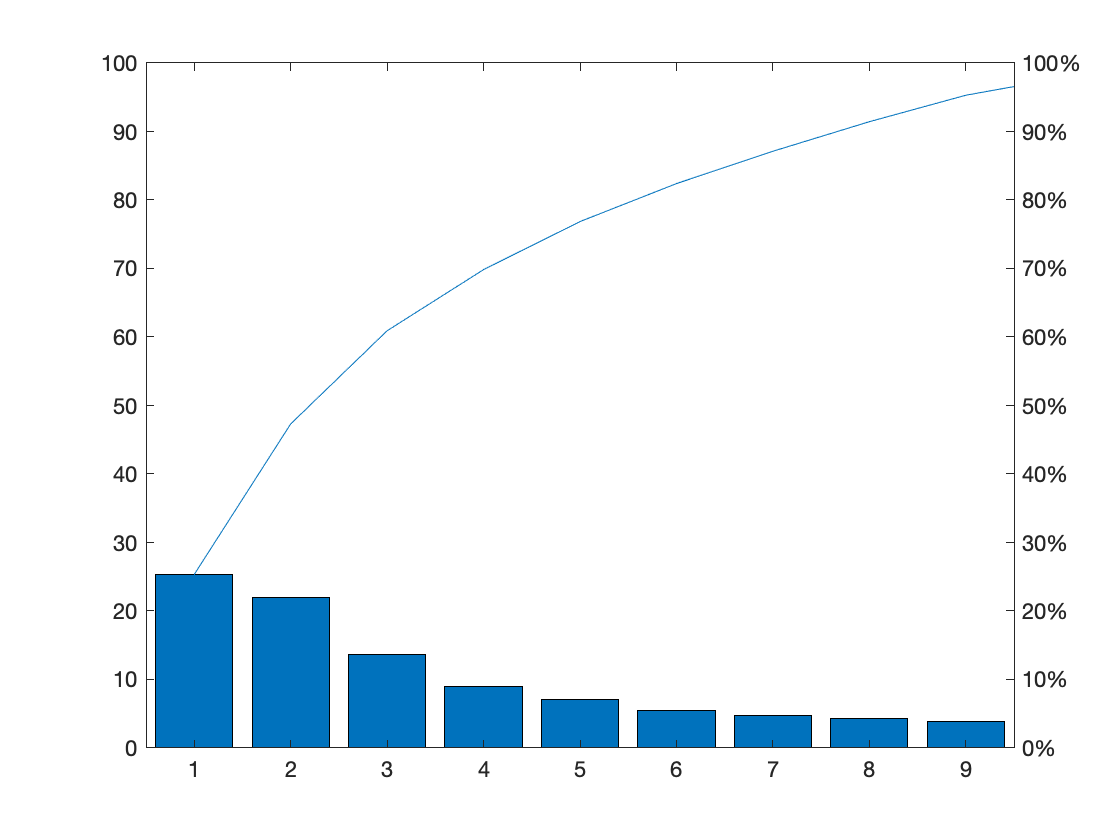

pareto(pexp)

## 7. Visualize the reduced data

Visualize the transformed data in two dimensions by making a scatter plot of the data in the first two components. Does it appear that there are distinct clusters?

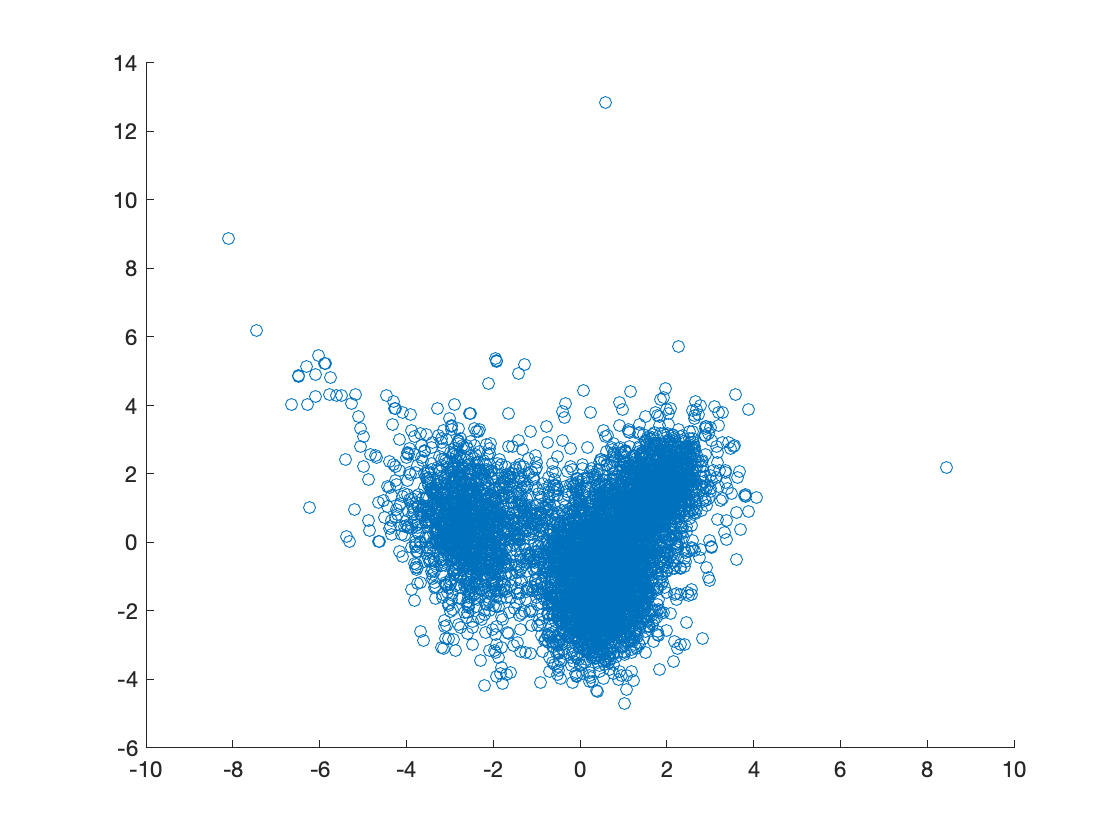

figure
scatter(scrs(:,1),scrs(:,2))

## 8. Cluster into 2 groups

Cluster the data into two groups. Experiment with *k*-means and/or GMM clustering, making grouped scatter plots to ensure that the clustering divides the data as you would expect.

Set random seed for reproducibility.

rng(1234)

*k*-means

[g,c]=kmeans(Z,2,"Replicates",5)

g =      2
     2
     2
     2
     1
     1
     2
     2
     2
     2


c =     0.8177    1.1598   -0.3382   -0.5896    0.9096   -0.8331   -1.1746    0.6682    0.5563    0.8245   -0.0820   -0.2660
   -0.2824   -0.4006    0.1168    0.2036   -0.3142    0.2878    0.4057   -0.2308   -0.1922   -0.2848    0.0283    0.0919


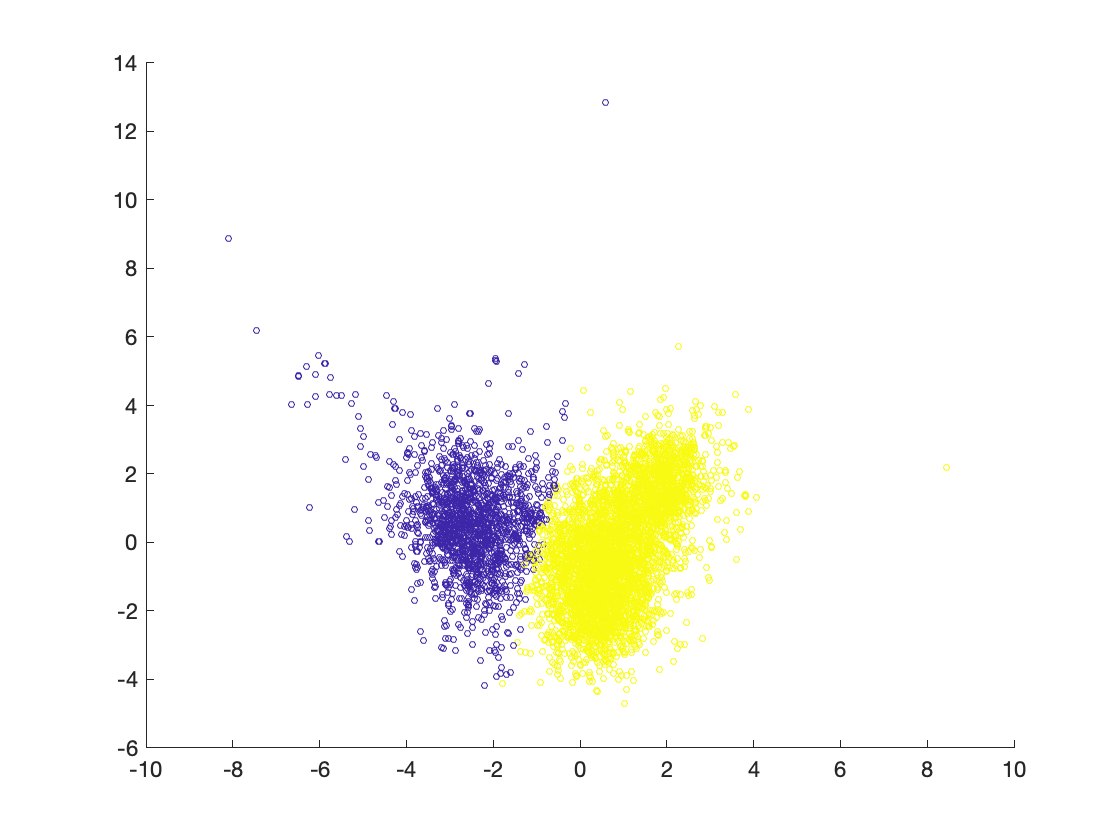

scatter(scrs(:,1),scrs(:,2),10,g)

GMM

gm = fitgmdist(Z,2,"Replicates",5,"RegularizationValue",0.03,"CovarianceType","diagonal") 

gm = 

12개 차원에 2개 성분을 갖는 가우스 혼합 분포




[g,~,p] = cluster(gm,Z) 

g =      2
     2
     2
     2
     1
     1
     2
     2
     2
     2


p =     0.0000    1.0000
    0.0000    1.0000
    0.0000    1.0000
    0.0000    1.0000
    1.0000    0.0000
    1.0000    0.0000
    0.0019    0.9981
    0.0000    1.0000
    0.0036    0.9964
    0.0000    1.0000


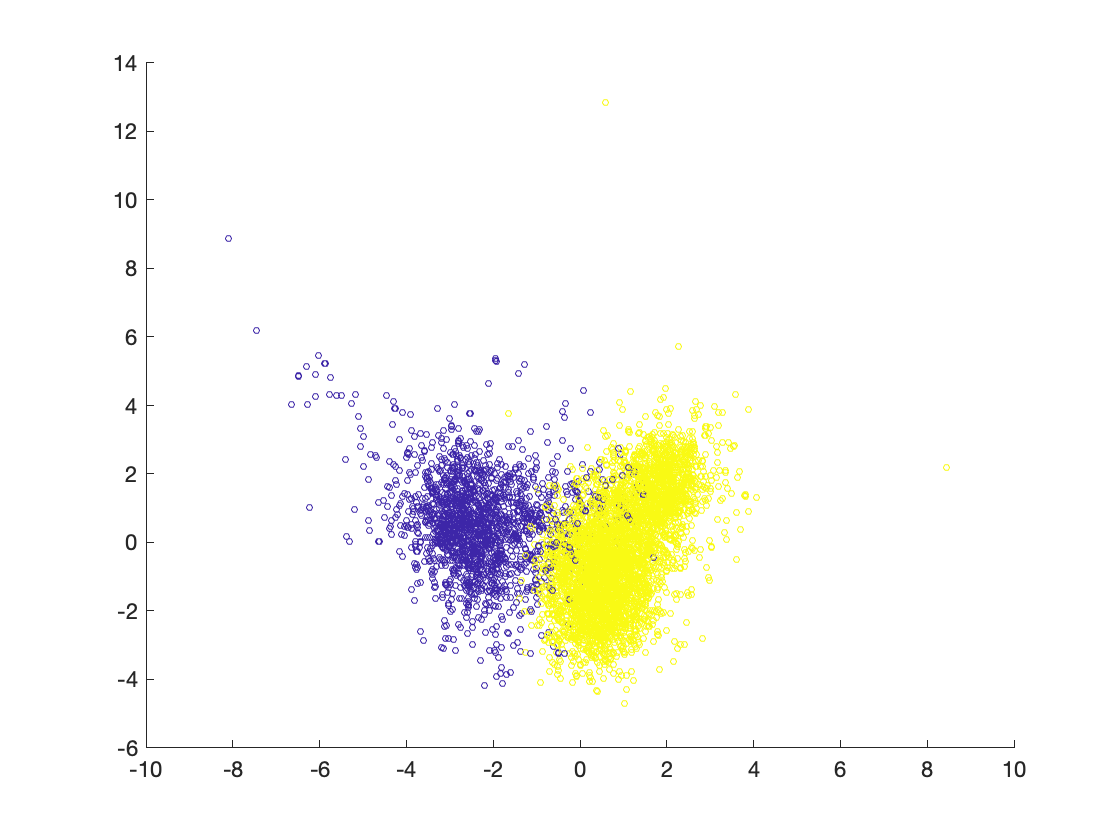


scatter(scrs(:,1),scrs(:,2),10,g)

## 9. Cross-tabulate grouping and wine color

Compare the resulting clusters with the groups in the `Color` variable using `crosstab`.

crosstab(g,data.Color)

ans =          265        1579
        4633          20
